clear
% Read img file
img = imread("../db/DB0/db0_1.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 


ans =

     []



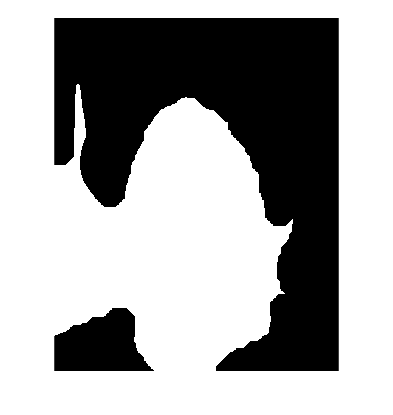

face_mask = facemask(img_gw);
imshow(face_mask)

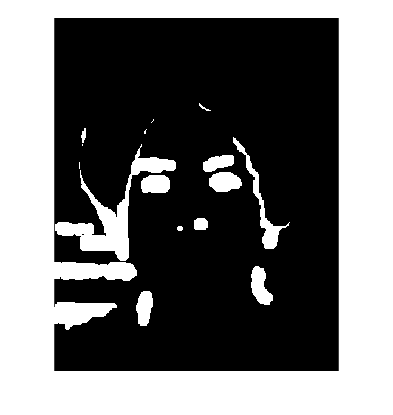


%Find eyes and a mouth
eyes = eyemap(img_gw);

eye_mask = eyemask(eyes) & face_mask;
imshow(eye_mask)

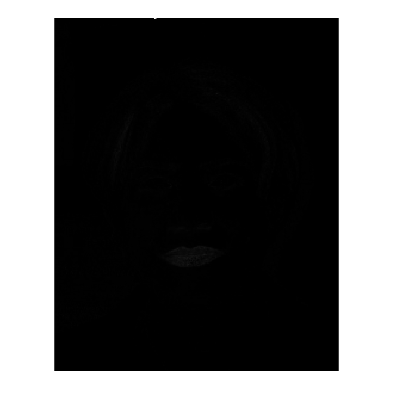


mouth = mouth_map(img_gw);
imshow(mouth)

mouth_mask = mouthmask(mouth) & face_mask;

imshow(mouth_mask)
[x,y] = mouth_index(mouth_mask)

x = 399

y = 225


[indexX,indexY] = eye_index(eye_mask)

indexX =     66    46    99    50   152   170   246   276   287   344   347


indexY =    425   494   313   196   487   280   347   243   276   300   450


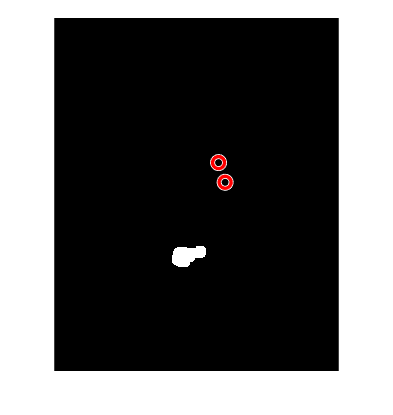

% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
[~, sorted_indices] = sort(distances);
selected_eye_indices = sorted_indices(1:2);

% Extract the coordinates of the selected eyes
selected_eyes = [indexX(selected_eye_indices), indexY(selected_eye_indices)];

viscircles([selected_eyes(1),selected_eyes(3)],10);
viscircles([selected_eyes(2),selected_eyes(4)],10);


%----------------------------------------%
[centers,radii,metric] = imfindcircles(img,[6 60],"Sensitivity",0.8,'ObjectPolarity','dark')

centers =    58.3128  425.3996
   87.3148  425.9661


radii =     7.2332
    6.7301


metric =     0.2679
    0.2414
